ch 50直下のピクセルにフォーカスをかける．

フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．

F値を固定する．最近接距離をいくつに設定する？

x-axis: 20 mmのときに全素子を使うという前提を設ける．

対象にする媒質データ：case26を用いる．

IMCL割合を0 %に固定する．

kgrid.x_vec が0となるのは251番目の要素．

グリッド幅が0.1 mm

素子間ピッチが0.4 mm

よって，最近接深度(最近接距離は0.4 mm)

深度ごとの細かい素子割当は，floor()を用いる．

整相加算の際に参照する音速を1580 m/sとする．

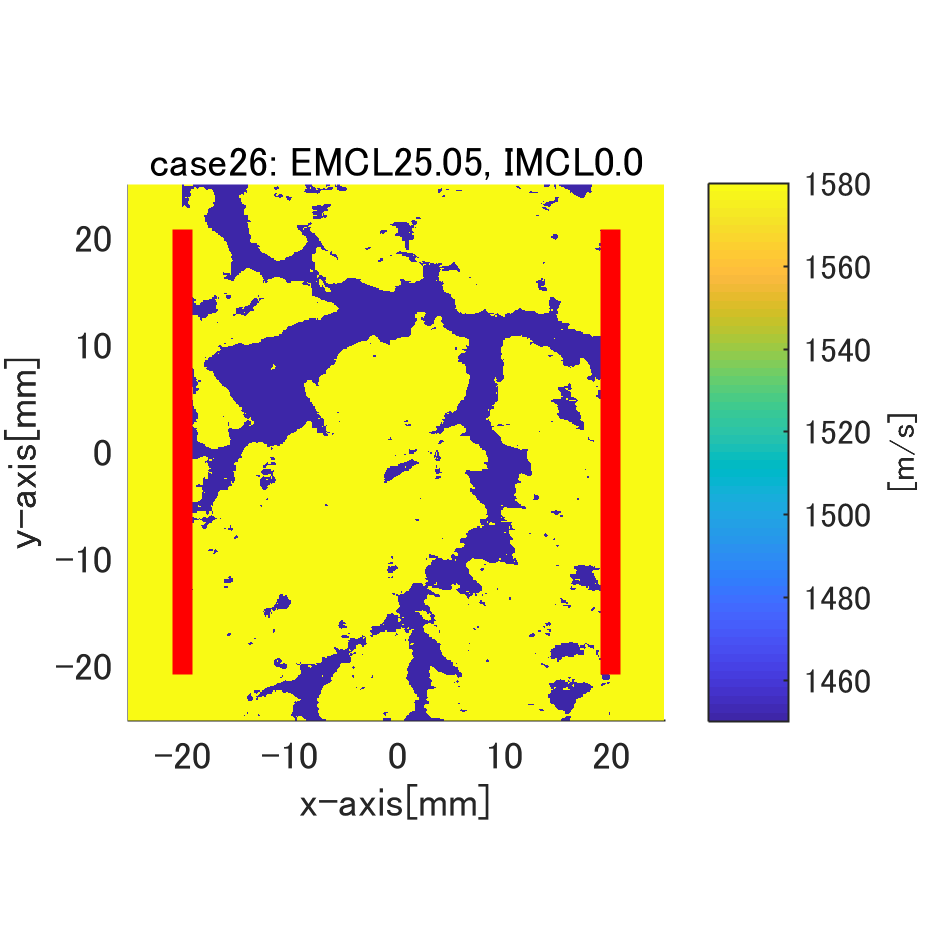

load("H:\data\kwave\medium\2018_09_28_realisticScatter_variousIMCL\corrected\case26_IMCL0.0.mat",'medium');
load("H:\data\kwave\config\t_pos_2board.mat");
load("H:\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\case26_IMCL0.0\rfdata.mat");
load("H:\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\case26_IMCL0.0\kgrid.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
v_reference = v_muscle;%[m/s]
t_facing_distance = 0.04;%[m]
num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
[num_sample,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
focused_rfdata = zeros(num_sample,num_echo_receiver,num_depth);
for ii = 1:num_depth
    focal_depth = (ii+3)*kgrid.dx;
    focal_point = [0;t_pos(2,1)-focal_depth];
    target_element = find((-focal_depth/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth/2)));
    distance_from_focal_point = zeros(1,length(target_element));
    for jj = 1:length(target_element)
        distance_from_focal_point(1,jj) = norm(t_pos(:,target_element(jj)) - focal_point);
        % 遅延処理
        delay_time = round(((distance_from_focal_point - focal_depth)/v_reference)/kgrid.dt);%[sample]
        read_range_rfdata = length(delay_time(jj)+1:num_sample);
        focused_rfdata(1:read_range_rfdata,:,ii) = focused_rfdata(1:read_range_rfdata,:,ii)...
            +  rfdata(delay_time(jj)+1:num_sample,1:100,target_element(jj));%整相加算
    end
end

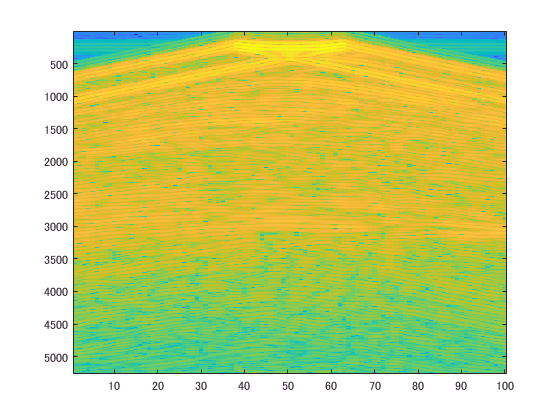

figure;
imagesc(20*log10((abs(focused_rfdata(:,:,100)))));

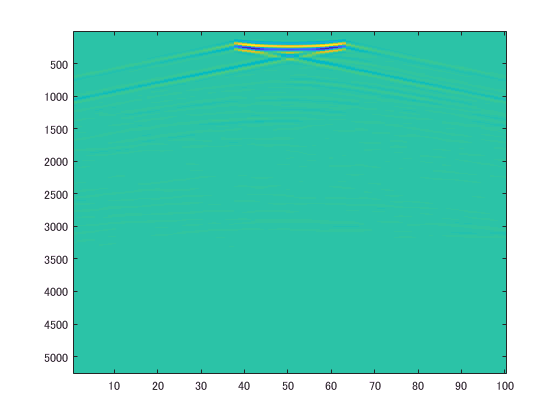

figure;
imagesc(focused_rfdata(:,:,100));

500 kHzではビームが収束していない？

5 MHzで試してみる．